clear all;
close all;

% Load preprocessed data from the previous step
fprintf('Loading preprocessed data from "Data/preprocessed_data.mat"...\n');

Loading preprocessed data from "Data/preprocessed_data.mat"...


load('../Data/preprocessed_data.mat', 'trainingInputs', 'trainingTargets','testInputs', 'testTargets');
fprintf('Preprocessed data loaded successfully.\n');

Preprocessed data loaded successfully.


% Configure the network with the best estimated feasible hyperparameters
fprintf('Configuring neural network with estimated best hyperparameters...\n');

Configuring neural network with estimated best hyperparameters...


% Define hidden layer size with 3 layers, each with 40 neurons as per the best estimated feasible point
bestHiddenLayerSize = repmat(40, 1, 3);  % Defines the network with three hidden layers, each containing 40 neurons

% Initialize feedforward neural network with the specified hidden layer size
net = feedforwardnet(bestHiddenLayerSize);  % Creates a feedforward network structure

% Set training parameters for the neural network according to the best estimated feasible point
net.trainFcn = 'trainrp';              % Set the training function to Resilient Backpropagation
net.performFcn = 'mse';                % Set the performance (loss) function to Mean Squared Error
net.trainParam.lr = 0.032172;          % Set the learning rate
net.trainParam.mc = 0.77721;           % Set the momentum parameter
net.trainParam.epochs = 35;            % Set the number of training epochs
net.divideFcn = 'dividetrain';         % Specify that all data will be used for training without further internal split

% Set activation function for each hidden layer
for i = 1:3
    net.layers{i}.transferFcn = 'tansig';  % Use the hyperbolic tangent sigmoid function for hidden layers
end



tic
% Train the network on the entire training dataset
fprintf('Training the neural network with estimated best hyperparameters...\n');

Training the neural network with estimated best hyperparameters...


[net, tr] = train(net, trainingInputs, trainingTargets);
fprintf('Training completed.\n');

Training completed.


toc

Elapsed time is 29.951911 seconds.



% save the 4 plots which comes in the UI after training
% Save generated plots after training
fprintf('Saving generated plots...\n');

Saving generated plots...


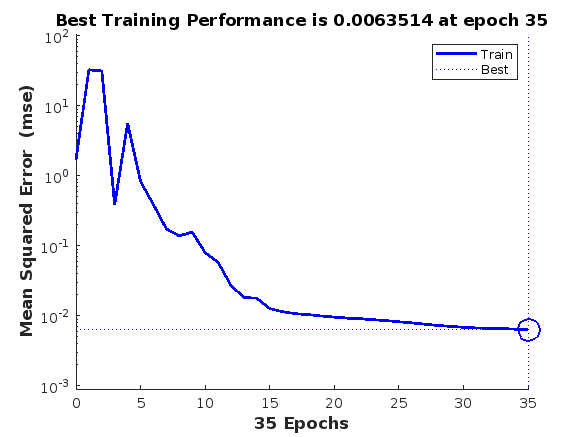


% Performance Plot
if isfield(tr, 'perf')
    figure, plotperform(tr);  % Generate the performance plot
    exportgraphics(gcf, '../outputs/exp3/performance_plot_best_feasible.png', 'Resolution', 300);  % Save performance plot with high resolution
    %close(gcf);  % Close the figure after saving
end

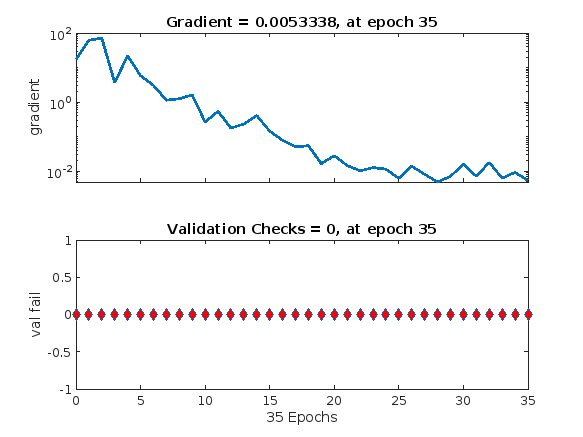


% Training State Plot
if isfield(tr, 'states')
    figure, plottrainstate(tr);  % Generate the training state plot
    exportgraphics(gcf, '../outputs/exp3/training_state_plot_best_feasible.png', 'Resolution', 300);  % Save training state plot with high resolution
    %close(gcf);
end


fprintf('All plots saved successfully.\n');

All plots saved successfully.



% Plot Training Progress for Training and Validation Loss and save
fprintf('Saving training progress plot to "../outputs/exp3/training_progress_best_feasible.png"...\n');

Saving training progress plot to "../outputs/exp3/training_progress_best_feasible.png"...


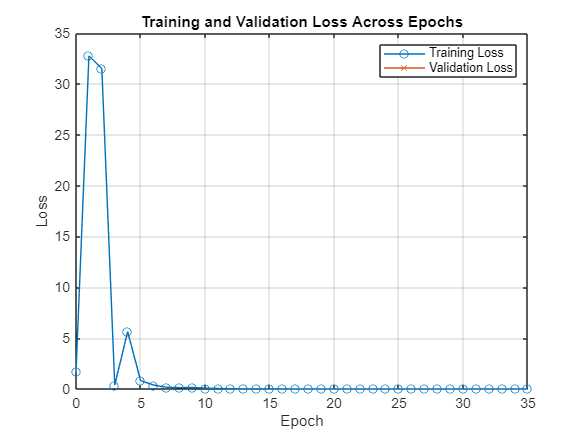

figure;
plot(tr.epoch, tr.perf, '-o', 'DisplayName', 'Training Loss');  % Plot training loss
hold on;
plot(tr.epoch, tr.vperf, '-x', 'DisplayName', 'Validation Loss');  % Plot validation loss

% Labels and styling
xlabel('Epoch');
ylabel('Loss');
title('Training and Validation Loss Across Epochs');
legend;
grid on;

% Save the plot as high-resolution image
exportgraphics(gcf, '../outputs/exp3/training_progress_best_feasible.png', 'Resolution', 300);

%%close(gcf);  % Close the figure after saving
fprintf('Training progress plot saved successfully.\n');

Training progress plot saved successfully.




% Save the trained network and training record with custom names
fprintf('Saving trained model to "Data/exp3/final_model_best_feasible.mat"...\n');

Saving trained model to "Data/exp3/final_model_best_feasible.mat"...


save('../Data/exp3/final_model_best_feasible.mat', 'net', 'tr');
fprintf('Trained model saved successfully.\n');

Trained model saved successfully.


## Prediction

% Load trained model and test data
fprintf('Loading trained model from "Data/exp3/final_model_best_feasible.mat"...\n');

Loading trained model from "Data/exp3/final_model_best_feasible.mat"...


load('../Data/exp3/final_model_best_feasible.mat', 'net');
fprintf('Best Feasible Trained model loaded successfully.\n');

Best Feasible Trained model loaded successfully.




% Perform predictions on the test data
fprintf('Predicting on the test data...\n');

Predicting on the test data...


predictedTestOutputs = net(testInputs);  % Raw outputs from network
predictedTestLabels = predictedTestOutputs >= 0.5;  % Convert to binary labels (assuming threshold of 0.5)

% Ensure both testTargets and predictedTestLabels are of type double
testTargets = double(testTargets);
predictedTestLabels = double(predictedTestLabels);

% Calculate accuracy
numCorrect = sum(predictedTestLabels == testTargets);
accuracy = numCorrect / length(testTargets) * 100;
fprintf('Accuracy on Test Data: %.2f%%\n', accuracy);

Accuracy on Test Data: 99.26%



% Save accuracy in a text file
metricsFile = fopen('../outputs/exp3/metrics_best_feasible.txt', 'w');
fprintf(metricsFile, 'Accuracy on Test Data: %.2f%%\n', accuracy);
fclose(metricsFile);


% Generate and save Confusion Matrix
fprintf('Generating confusion matrix...\n');

Generating confusion matrix...


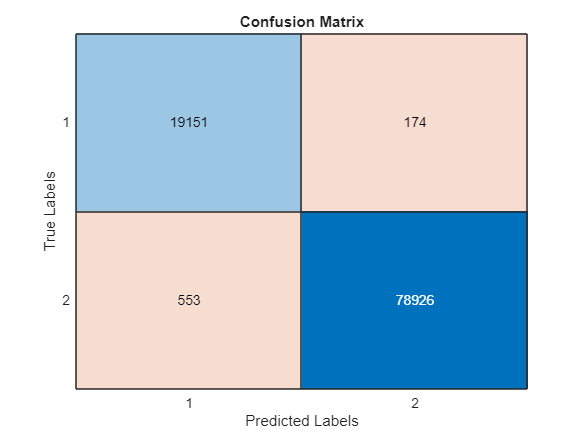

% Compute the rounded confusion matrix
confMat = round(confusionmat(testTargets, predictedTestLabels));

% Display the confusion matrix using confusionchart
figure;
cm = confusionchart(confMat);

% Set properties to show numbers without scientific notation
cm.CellLabelFormat = '%d';  % Format labels as integers

% Customize the chart title and labels as needed
cm.Title = 'Confusion Matrix';
cm.XLabel = 'Predicted Labels';
cm.YLabel = 'True Labels';

% Save the confusion matrix plot as a high-resolution PNG file
exportgraphics(gcf, '../outputs/exp3/confusion_matrix_best_feasible.png', 'Resolution', 300);

fprintf('Confusion matrix saved as "outputs/exp3/confusion_matrix_best_feasible.png" with high resolution.\n');

Confusion matrix saved as "outputs/exp3/confusion_matrix_best_feasible.png" with high resolution.




% Calculate additional metrics (Precision, Recall, F1 Score)
truePositives = sum(predictedTestLabels == 1 & testTargets == 1);
trueNegatives = sum(predictedTestLabels == 0 & testTargets == 0);
falsePositives = sum(predictedTestLabels == 1 & testTargets == 0);
falseNegatives = sum(predictedTestLabels == 0 & testTargets == 1);

precision = truePositives / (truePositives + falsePositives);
recall = truePositives / (truePositives + falseNegatives);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 99.78%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 99.30%


fprintf('F1 Score: %.2f%%\n', f1Score * 100);

F1 Score: 99.54%



% Save additional metrics
metricsFile = fopen('../outputs/exp3/metrics_best_feasible.txt', 'a');  % Open in append mode
fprintf(metricsFile, 'Precision: %.2f%%\n', precision * 100);
fprintf(metricsFile, 'Recall: %.2f%%\n', recall * 100);
fprintf(metricsFile, 'F1 Score: %.2f%%\n', f1Score * 100);
fclose(metricsFile);


% Generate ROC Curve and save
fprintf('Generating ROC curve...\n');

Generating ROC curve...


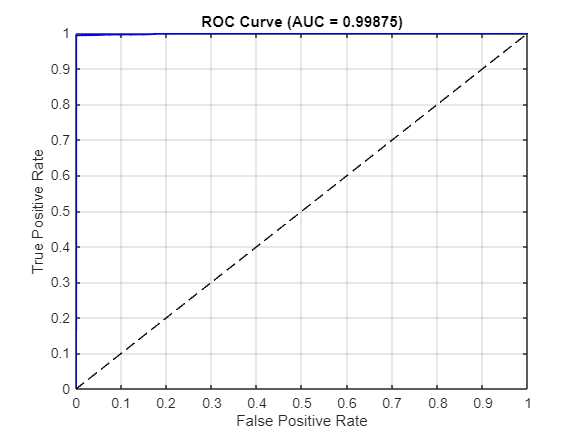

[X, Y, T, AUC] = perfcurve(testTargets, predictedTestOutputs, 1);
figure;
plot(X, Y, '-b', 'LineWidth', 1.5);
hold on;
plot([0 1], [0 1], '--k');  % Diagonal line for random guessing
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve (AUC = ', num2str(AUC), ')']);
grid on;

% Save the ROC curve as a high-resolution PNG file
exportgraphics(gcf, '../outputs/exp3/roc_curve_best_feasible.png', 'Resolution', 300);

fprintf('ROC curve saved as "../outputs/exp3/roc_curve_best_feasible.png" with high resolution.\n');

ROC curve saved as "../outputs/exp3/roc_curve_best_feasible.png" with high resolution.
